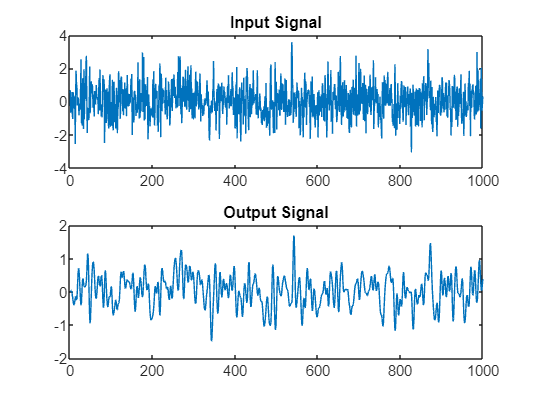

% Define the filter order and cutoff frequency
order = 4;
cutoffFreq = 0.2;

% Design the IIR filter
[b, a] = butter(order, cutoffFreq);

% Apply the filter to a signal
inputSignal = randn(1, 1000); % Example input signal
outputSignal = filter(b, a, inputSignal);

% Plot the input and output signals
subplot(2,1,1);
plot(inputSignal);
title('Input Signal');
subplot(2,1,2);
plot(outputSignal);
title('Output Signal');

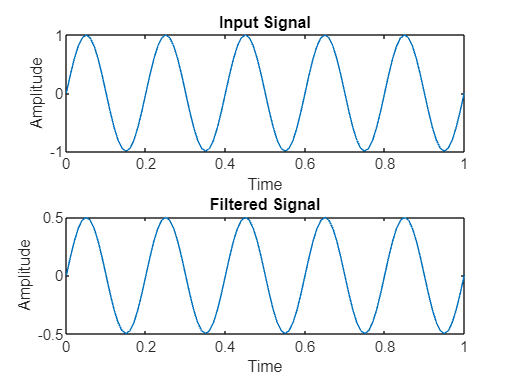

% Define the filter coefficients
b = [0.5, -0.25, 0.1]; % numerator coefficients
a = [1, -0.5, 0.2]; % denominator coefficients

% Generate an input signal
t = 0:0.01:1; % time vector
x = sin(2*pi*5*t); % input signal (5 Hz sine wave)

% Initialize the output signal
y = zeros(size(x));

% Apply the filter to the input signal
for n = 1:length(x)
    y(n) = b(1)*x(n);
    for k = 2:length(b)
        if n-k+1 > 0
            y(n) = y(n) + b(k)*x(n-k+1);
        end
    end
    for k = 2:length(a)
        if n-k+1 > 0
            y(n) = y(n) - a(k)*y(n-k+1);
        end
    end
end

% Plot the input and filtered signals
subplot(2,1,1);
plot(t, x);
title('Input Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, y);
title('Filtered Signal');
xlabel('Time');
ylabel('Amplitude');